# Case2：用风最优分布的案例

clc
clear
close

## 1. 建一个子问题

这里先定义一下环境

Surnode =  [530	3125
            740	2750
            970	2375
            1240	2500
            1200	2000
            1180	1750
            660	1750
            700	2250
            240	2500];

Model1.Airnode = [280	3000
                  780	3250];
Model1.centrol = [530	3125];
Model1.Surnode = [240	2500
                  740	2750
                  1240	2500];
Model1.CostAir = [800; 800];
Model1.CostSur = [800; 800; 800];

Model2.Airnode = [700	2250
            1240	2500];
Model2.centrol = [970	2375];
Model2.Surnode = [740	2750
            1240	2500
            1200 2200];
Model2.CostAir = [800; 800];
Model2.CostSur = [800; 800; 800];

Model3.Airnode = [1200	2000
            1160	1500];
Model3.centrol = [1180	1750];
Model3.Surnode = [1200	2000
            660	1750];
Model3.CostAir = [800; 800];
Model3.CostSur = [800; 800; 800];

Vel.us = [1];
Vel.ua = [20];

然后定义一下优化参数

iter_Max=200;
N=200;
range=100;
ub = [Model2.Airnode(1,1)+range,Model2.Airnode(1,2)+range];
lb = [Model2.Airnode(1,1)-range,Model2.Airnode(1,2)-range];

[Temp_T, GBestFitness, Temp_L] = PSOsolveTemp(Model2, Vel, ub, lb, iter_Max, N)

Temp_T =          800        2350


GBestFitness = 1.0e+03 *

    1.1981    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720    1.1720


Temp_L =         1200        2200


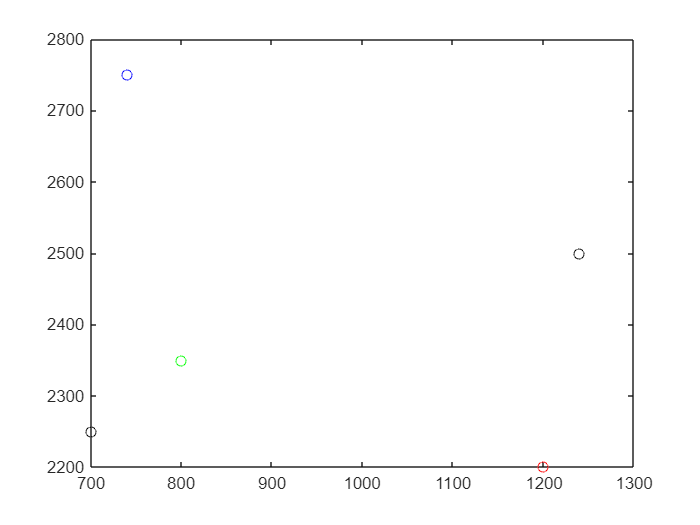

close
figure
plot(Model2.Surnode(:,1),Model2.Surnode(:,2),'bo');
hold on
plot(Model2.Airnode(:,1),Model2.Airnode(:,2),'ko');
plot(Temp_T(1),Temp_T(2),'go');
plot(Temp_L(1),Temp_L(2),'ro');

## 2.

clc
clear
close

% 定义
Model1.Airnode = [280	3000
                  780	3250];
Model1.centrol = [530	3125];
Model1.Surnode = [240	2500
                  740	2750
                  1240	2500];
Model1.CostAir = [800; 800];
Model1.CostSur = [800; 800; 800];

Vel.us = [1];
Vel.ua = [20];

iter_Max=200;
N=200;
range=100;
D = 2; % 决策变量维度
ub = [Model1.Airnode(1,1)+range,Model1.Airnode(1,2)+range];
lb = [Model1.Airnode(1,1)-range,Model1.Airnode(1,2)-range];

% 计算起点
Temp_T = [380,3000];

% 计算UAV任务耗时
ua = Vel.ua;
Airnode = [Temp_T; Model1.Airnode];
AirLength = 0;
for i=2:length(Airnode)
    AirLength = AirLength + sqrt((Airnode(i,1)-Airnode(i-1,1))^2 + (Airnode(i,2)-Airnode(i-1,2))^2);
end
TimeA = sum(Model1.CostAir) + AirLength/ua;

% 计算USV任务序列
us = Vel.us;
Surnode = [Temp_T; Model1.Surnode(2:end,:)];
CostSur = [0; Model1.CostSur(2:end)];
TimeS(1) = 0;
item=2;
Temp_L = [];



for i=2:length(Surnode)
        TimeS(item) = TimeS(item-1) + sqrt((Surnode(i,1)-Surnode(i-1,1))^2 + (Surnode(i,2)-Surnode(i-1,2))^2) / us;
        if TimeS(item) > TimeA
            % 在航行中UAV完工了
            DeltaV = sqrt((Surnode(i-1,1)-Airnode(end,1))^2 + (Surnode(i-1,2)-Airnode(end,2))^2);
            DeltaT = (DeltaV-(TimeA-TimeS(item-1))*us)/(ua+us);
            dal = DeltaT * ua;
            Temp_L = dal/DeltaV * Airnode(end,:) + (1-dal/DeltaV) * Surnode(i-1,:);

            place = i; % 插在Temp_T后i个
            Flag = 1;
            break
        end
        item = item + 1;
        TimeS(item) = TimeS(item-1) + CostSur(i);
        if TimeS(item) > TimeA
            % 在工作中UAV完工了
            Temp_L = Surnode(i,:);

            place = i; % 不用插
            Flag = 2;
            break
        end
        item = item + 1;
end

if Flag==1
    if place==1
        Surnode = [Model1.Surnode(1,:); Temp_T; Temp_L; Model1.Surnode(2:end,:)];
    else 
        Surnode = [Model1.Surnode(1,:); Temp_T; Model1.Surnode(2:place-1,:); Temp_L; Model1.Surnode(place:end,:)];
    end
elseif Flag==2
    Surnode = [Model1.Surnode(1,:); Temp_T; Model1.Surnode(2:end,:)];
elseif Flag==0
    Surnode = [Model1.Surnode(1,:); Temp_T; Model1.Surnode(2:end,:); Temp_L;];
end

## 正式开始！

定义一些参数

clc
clear
close

iter_Max=20;
N=200;
range=100;

Vel.us = [1];
Vel.ua = [20];

## 1号组

Model1.Airnode = [540	250];
Model1.centrol = [540	250];
Model1.Surnode = [120	1000
                540	250
                1080	500];
Model1.CostAir = [800];
Model1.CostSur = [800; 800; 800];
ub = [Model1.Airnode(1,1)+range,Model1.Airnode(1,2)+range];
lb = [Model1.Airnode(1,1)-range,Model1.Airnode(1,2)-range];

[Temp_T1, GBestFitness, Temp_L1] = PSOsolveTemp(Model1, Vel, ub, lb, iter_Max, N)

Temp_T1 =   497.4732  325.9404


GBestFitness = 1.0e+03 *

    1.4547    1.4547    1.4547    1.4547    1.4547    1.4547    1.4547    1.4547    1.4547    1.4547    1.4547    1.4547    1.4547    1.4547    1.4547    1.4547    1.4547    1.4547    1.4547    1.4547    1.4547


Temp_L1 =    540   250


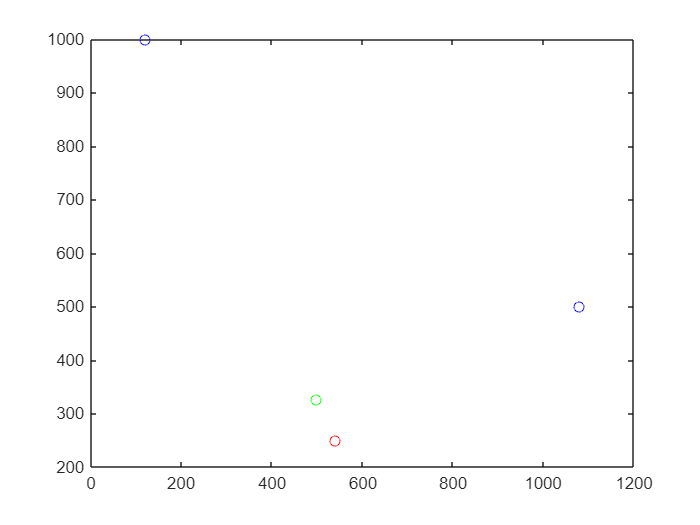


close
figure
plot(Model1.Surnode(:,1),Model1.Surnode(:,2),'bo');
hold on
plot(Model1.Airnode(:,1),Model1.Airnode(:,2),'ko');
plot(Temp_T1(1),Temp_T1(2),'go');
plot(Temp_L1(1),Temp_L1(2),'ro');

Model2.Airnode = [1080	500
                  1580	750];
Model2.centrol = [1330	625];
Model2.Surnode = [1080	500
                    2540	250];
Model2.CostAir = [800; 800];
Model2.CostSur = [800; 800];
ub = [Model2.Airnode(1,1)+range,Model2.Airnode(1,2)+range];
lb = [Model2.Airnode(1,1)-range,Model2.Airnode(1,2)-range];

[Temp_T2, GBestFitness, Temp_L2] = PSOsolveTemp(Model2, Vel, ub, lb, iter_Max, N)

Temp_T2 = 1.0e+03 *

    1.1799    0.4829


GBestFitness = 1.0e+03 *

    1.4813    1.4812    1.4812    1.4812    1.4812    1.4812    1.4812    1.4812    1.4812    1.4812    1.4812    1.4812    1.4812    1.4812    1.4812    1.4812    1.4812    1.4812    1.4812    1.4812    1.4812


Temp_L2 =         2540         250


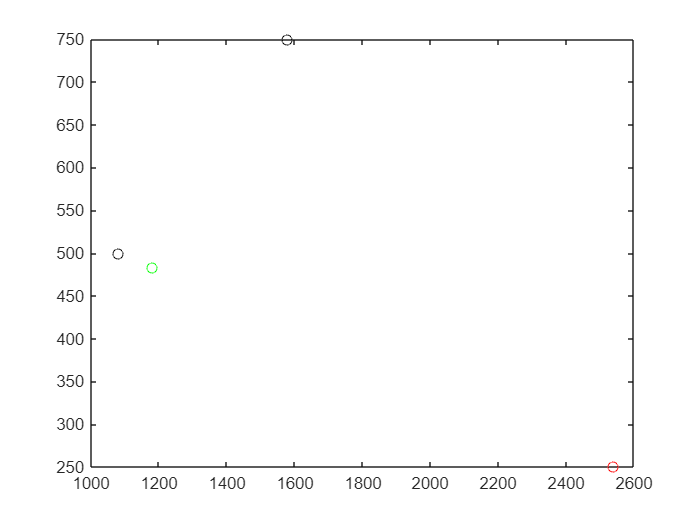


close
figure
plot(Model2.Surnode(:,1),Model2.Surnode(:,2),'bo');
hold on
plot(Model2.Airnode(:,1),Model2.Airnode(:,2),'ko');
plot(Temp_T2(1),Temp_T2(2),'go');
plot(Temp_L2(1),Temp_L2(2),'ro');

Model3.Airnode = [2540	250
                  3120 1000];
Model3.centrol = [2830	625];
Model3.Surnode = [2540	250
                    2580	750
                    620	1250];
Model3.CostAir = [800; 800];
Model3.CostSur = [800; 800; 800];
ub = [Model3.Airnode(1,1)+range,Model3.Airnode(1,2)+range];
lb = [Model3.Airnode(1,1)-range,Model3.Airnode(1,2)-range];

[Temp_T3, GBestFitness, Temp_L3] = PSOsolveTemp(Model3, Vel, ub, lb, iter_Max, N)

Temp_T3 = 1.0e+03 *

    2.5739    0.3500


GBestFitness = 1.0e+03 *

    2.7511    2.7389    2.7389    2.7389    2.7389    2.7389    2.7389    2.7389    2.7389    2.7389    2.7389    2.7389    2.7389    2.7389    2.7389    2.7389    2.7389    2.7389    2.7389    2.7389    2.7389


Temp_L3 = 1.0e+03 *

    2.7031    0.8070


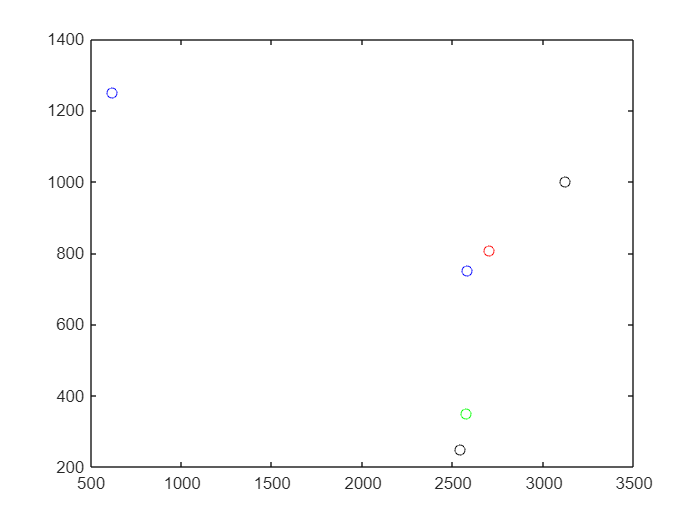


close
figure
plot(Model3.Surnode(:,1),Model3.Surnode(:,2),'bo');
hold on
plot(Model3.Airnode(:,1),Model3.Airnode(:,2),'ko');
plot(Temp_T3(1),Temp_T3(2),'go');
plot(Temp_L3(1),Temp_L3(2),'ro');

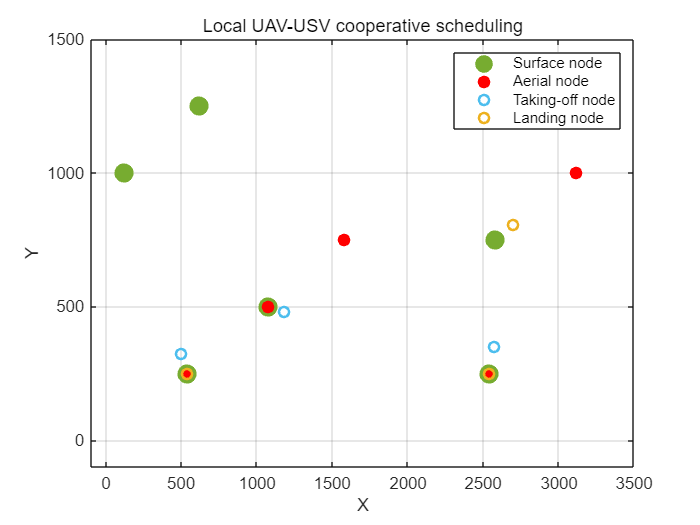

close
Surnode =  [Model1.Surnode
            Model2.Surnode
             Model3.Surnode];

Airnode = [Model1.Airnode
            Model2.Airnode
            Model3.Airnode];

Temp_T = [Temp_T1
    Temp_T2
    Temp_T3];

Temp_L = [Temp_L1
    Temp_L2
    Temp_L3];

figure
plot([Surnode(:, 1)], [Surnode(:, 2)], 'o', 'Color', "#77AC30" ,'MarkerFaceColor', "#77AC30",'MarkerSize',10,'LineWidth',1.5);
hold on;
plot([Airnode(:, 1)], [Airnode(:, 2)], 'o', 'Color', "#FF0000" ,'MarkerFaceColor', '#FF0000','MarkerSize',6,'LineWidth',1.5);
plot([Temp_T(:, 1)], [Temp_T(:, 2)], 'o', 'Color', "#4DBEEE" ,'MarkerSize',6,'LineWidth',1.5);
plot([Temp_L(:, 1)], [Temp_L(:, 2)], 'o', 'Color', "#EDB120" ,'MarkerSize',6,'LineWidth',1.5);


hold off
legend('Surface node','Aerial node','Taking-off node','Landing node')
axis([-100 3500 -100 1500])
title('Local UAV-USV cooperative scheduling');
xlabel('X');
ylabel('Y');
grid on;

## 2号组

Model1.Airnode = [1660 1750
                   1700 2250];
Model1.centrol = [1680	2000];
Model1.Surnode = [1620	1250
                1700	2250
                1740	2750];
Model1.CostAir = [800;  800];
Model1.CostSur = [800; 1600; 800];
ub = [Model1.Airnode(1,1)+range,Model1.Airnode(1,2)+range];
lb = [Model1.Airnode(1,1)-range,Model1.Airnode(1,2)-range];

[Temp_T1, GBestFitness, Temp_L1] = PSOsolveTemp(Model1, Vel, ub, lb, iter_Max, N)

Temp_T1 = 1.0e+03 *

    1.6568    1.7105


GBestFitness = 1.0e+03 *

    1.5048    1.5048    1.5048    1.5048    1.5048    1.5048    1.5048    1.5048    1.5048    1.5048    1.5048    1.5048    1.5048    1.5048    1.5048    1.5048    1.5048    1.5048    1.5048    1.5048    1.5048


Temp_L1 =         1700        2250


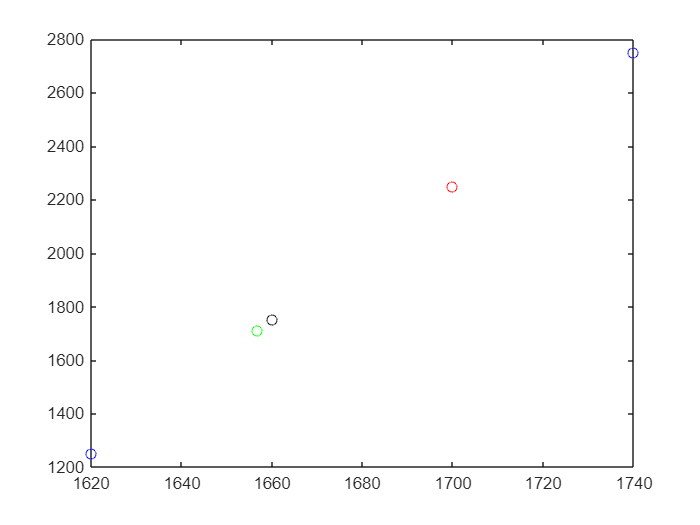


close
figure
plot(Model1.Surnode(:,1),Model1.Surnode(:,2),'bo');
hold on
plot(Model1.Airnode(:,1),Model1.Airnode(:,2),'ko');
plot(Temp_T1(1),Temp_T1(2),'go');
plot(Temp_L1(1),Temp_L1(2),'ro');

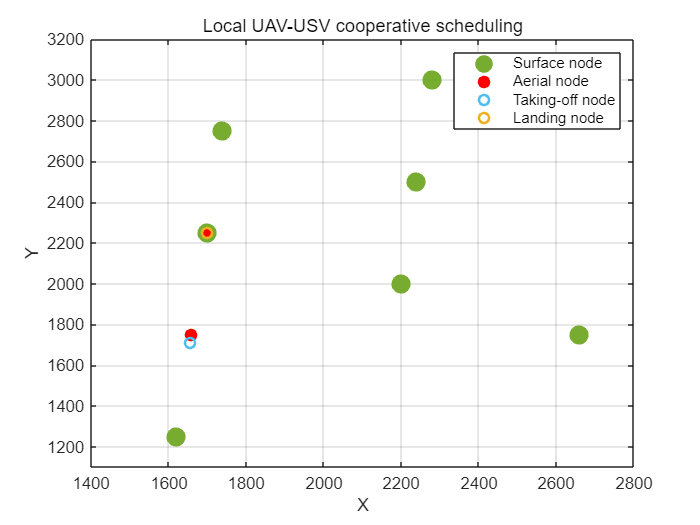

close
Surnode =  [1700	2250
1740	2750
2280	3000
2240	2500
2200	2000
2660	1750
1620	1250];

Airnode = [Model1.Airnode];

Temp_T = [Temp_T1];

Temp_L = [Temp_L1];

figure
plot([Surnode(:, 1)], [Surnode(:, 2)], 'o', 'Color', "#77AC30" ,'MarkerFaceColor', "#77AC30",'MarkerSize',10,'LineWidth',1.5);
hold on;
plot([Airnode(:, 1)], [Airnode(:, 2)], 'o', 'Color', "#FF0000" ,'MarkerFaceColor', '#FF0000','MarkerSize',6,'LineWidth',1.5);
plot([Temp_T(:, 1)], [Temp_T(:, 2)], 'o', 'Color', "#4DBEEE" ,'MarkerSize',6,'LineWidth',1.5);
plot([Temp_L(:, 1)], [Temp_L(:, 2)], 'o', 'Color', "#EDB120" ,'MarkerSize',6,'LineWidth',1.5);


hold off
legend('Surface node','Aerial node','Taking-off node','Landing node')
axis([1400 2800 1100 3200])
title('Local UAV-USV cooperative scheduling');
xlabel('X');
ylabel('Y');
grid on;

## 3号组

Model1.Airnode = [280	3000
                  780	3250];
Model1.centrol = [530	3125];
Model1.Surnode = [240	2500
                  740	2750
                  1240	2500];
Model1.CostAir = [800; 800];
Model1.CostSur = [800; 800; 800];
ub = [Model1.Airnode(1,1)+range,Model1.Airnode(1,2)+range];
lb = [Model1.Airnode(1,1)-range,Model1.Airnode(1,2)-range];

[Temp_T1, GBestFitness, Temp_L1] = PSOsolveTemp(Model1, Vel, ub, lb, iter_Max, N)

Temp_T1 =          380        2900


GBestFitness = 1.0e+03 *

    1.4294    1.4135    1.4135    1.4135    1.4135    1.4135    1.4135    1.4135    1.4135    1.4135    1.4135    1.4135    1.4135    1.4135    1.4135    1.4135    1.4135    1.4135    1.4135    1.4135    1.4135


Temp_L1 = 1.0e+03 *

    0.7443    2.8037


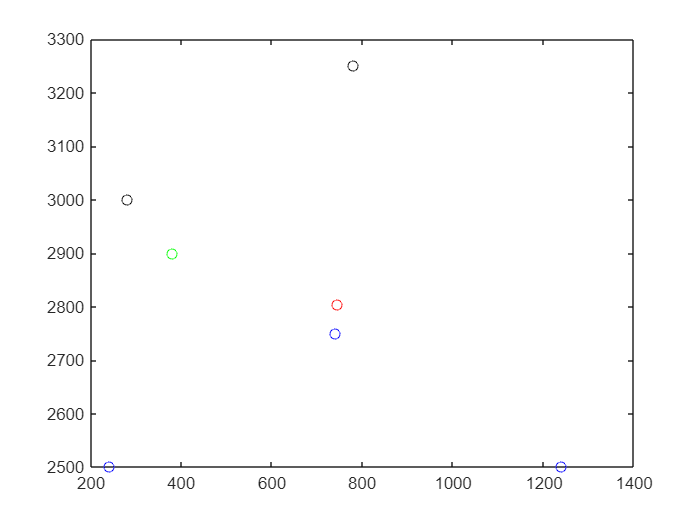


close
figure
plot(Model1.Surnode(:,1),Model1.Surnode(:,2),'bo');
hold on
plot(Model1.Airnode(:,1),Model1.Airnode(:,2),'ko');
plot(Temp_T1(1),Temp_T1(2),'go');
plot(Temp_L1(1),Temp_L1(2),'ro');

Model2.Airnode = [700	2250
                  1240	2500];
Model2.centrol = [970	2375];
Model2.Surnode = [740	2750
                  1240	2500
                  1200	2000];
Model2.CostAir = [800; 800];
Model2.CostSur = [800; 1600; 800];
ub = [Model2.Airnode(1,1)+range,Model2.Airnode(1,2)+range];
lb = [Model2.Airnode(1,1)-range,Model2.Airnode(1,2)-range];

[Temp_T2, GBestFitness, Temp_L2] = PSOsolveTemp(Model2, Vel, ub, lb, iter_Max, N)

Temp_T2 =          800        2350


GBestFitness = 1.0e+03 *

    1.3883    1.3709    1.3709    1.3709    1.3709    1.3709    1.3709    1.3709    1.3709    1.3709    1.3709    1.3709    1.3709    1.3709    1.3709    1.3709    1.3709    1.3709    1.3709    1.3709    1.3709


Temp_L2 =         1240        2500


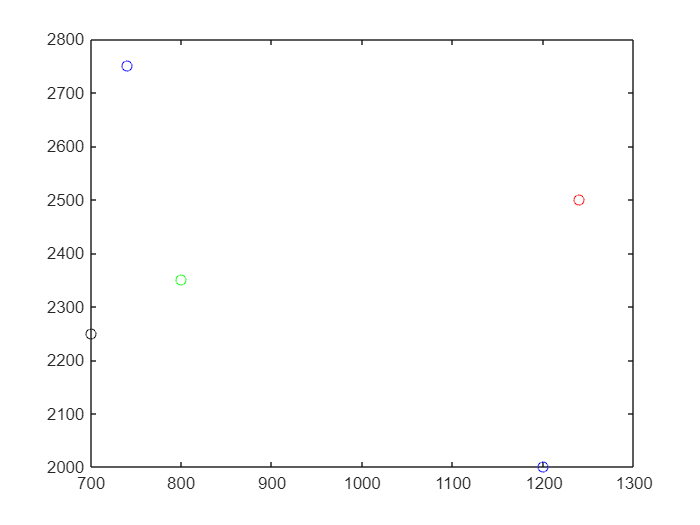


close
figure
plot(Model2.Surnode(:,1),Model2.Surnode(:,2),'bo');
hold on
plot(Model2.Airnode(:,1),Model2.Airnode(:,2),'ko');
plot(Temp_T2(1),Temp_T2(2),'go');
plot(Temp_L2(1),Temp_L2(2),'ro');

Model3.Airnode = [1200	2000
                  1160	1500];
Model3.centrol = [1180	1750];
Model3.Surnode = [1200	2000
                  660	1750
                  700 2250];
Model3.CostAir = [800; 800];
Model3.CostSur = [800; 800; 800];
ub = [Model3.Airnode(1,1)+range,Model3.Airnode(1,2)+range];
lb = [Model3.Airnode(1,1)-range,Model3.Airnode(1,2)-range];

[Temp_T3, GBestFitness, Temp_L3] = PSOsolveTemp(Model3, Vel, ub, lb, iter_Max, N)

Temp_T3 =         1100        1900


GBestFitness = 1.0e+03 *

    1.1941    1.1865    1.1865    1.1865    1.1865    1.1865    1.1865    1.1865    1.1865    1.1865    1.1865    1.1865    1.1865    1.1865    1.1865    1.1865    1.1865    1.1865    1.1865    1.1865    1.1865


Temp_L3 = 1.0e+03 *

    0.8233    1.6683


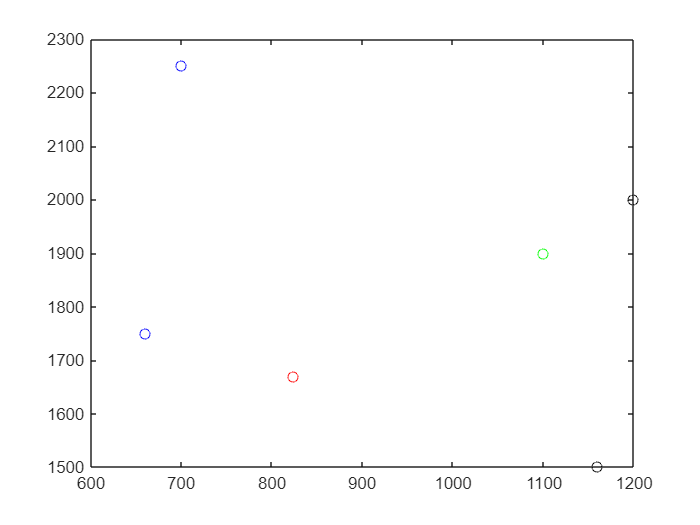


close
figure
plot(Model3.Surnode(:,1),Model3.Surnode(:,2),'bo');
hold on
plot(Model3.Airnode(:,1),Model3.Airnode(:,2),'ko');
plot(Temp_T3(1),Temp_T3(2),'go');
plot(Temp_L3(1),Temp_L3(2),'ro');

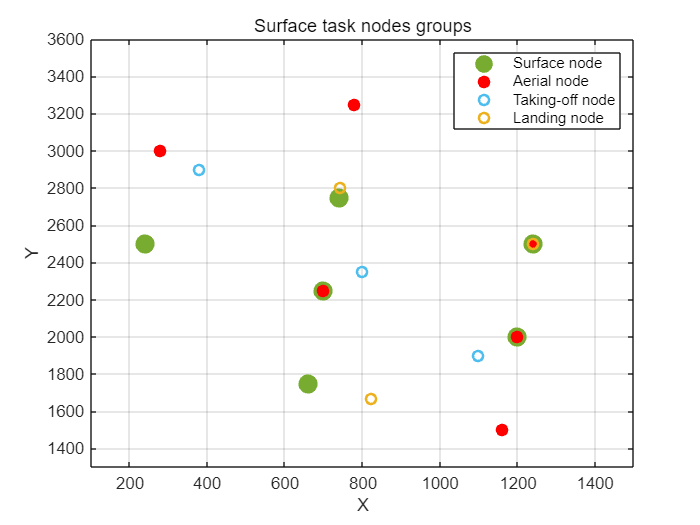

close
Surnode =  [Model1.Surnode
            Model2.Surnode
             Model3.Surnode];

Airnode = [Model1.Airnode
            Model2.Airnode
            Model3.Airnode];

Temp_T = [Temp_T1
    Temp_T2
    Temp_T3];

Temp_L = [Temp_L1
    Temp_L2
    Temp_L3];

figure
plot([Surnode(:, 1)], [Surnode(:, 2)], 'o', 'Color', "#77AC30" ,'MarkerFaceColor', "#77AC30",'MarkerSize',10,'LineWidth',1.5);
hold on;
plot([Airnode(:, 1)], [Airnode(:, 2)], 'o', 'Color', "#FF0000" ,'MarkerFaceColor', '#FF0000','MarkerSize',6,'LineWidth',1.5);
plot([Temp_T(:, 1)], [Temp_T(:, 2)], 'o', 'Color', "#4DBEEE" ,'MarkerSize',6,'LineWidth',1.5);
plot([Temp_L(:, 1)], [Temp_L(:, 2)], 'o', 'Color', "#EDB120" ,'MarkerSize',6,'LineWidth',1.5);


hold off
legend('Surface node','Aerial node','Taking-off node','Landing node')
axis([100 1500 1300 3600])
title('Surface task nodes groups');
xlabel('X');
ylabel('Y');
grid on;

## 4号组

Model1.Airnode = [2740 2750
                2280 3000];
Model1.centrol = [2510	2875];
Model1.Surnode = [3200	2000
                2740	2750
                2780	3250];
Model1.CostAir = [800; 800];
Model1.CostSur = [800; 800; 800];
ub = [Model1.Airnode(1,1)+range,Model1.Airnode(1,2)+range];
lb = [Model1.Airnode(1,1)-range,Model1.Airnode(1,2)-range];

[Temp_T1, GBestFitness, Temp_L1] = PSOsolveTemp(Model1, Vel, ub, lb, iter_Max, N)

Temp_T1 = 1.0e+03 *

    2.8013    2.6500


GBestFitness = 1.0e+03 *

    1.3814    1.3814    1.3814    1.3814    1.3814    1.3814    1.3814    1.3814    1.3814    1.3814    1.3814    1.3814    1.3814    1.3814    1.3814    1.3814    1.3814    1.3814    1.3814    1.3814    1.3814


Temp_L1 =         2780        3250


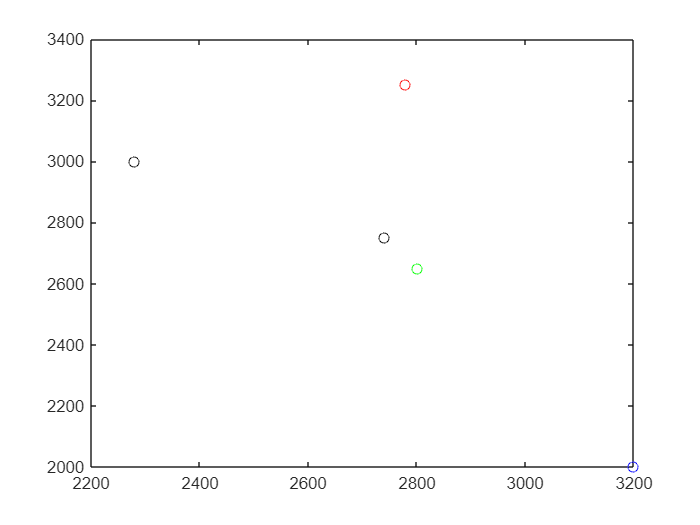


close
figure
plot(Model1.Surnode(:,1),Model1.Surnode(:,2),'bo');
hold on
plot(Model1.Airnode(:,1),Model1.Airnode(:,2),'ko');
plot(Temp_T1(1),Temp_T1(2),'go');
plot(Temp_L1(1),Temp_L1(2),'ro');

Model2.Airnode = [2780 3250];
Model2.centrol = [2780	3250];
Model2.Surnode = [2740	2750
                    2780	3250
                    3280	3000];
Model2.CostAir = [800];
Model2.CostSur = [800; 800; 800];
ub = [Model2.Airnode(1,1)+range,Model2.Airnode(1,2)+range];
lb = [Model2.Airnode(1,1)-range,Model2.Airnode(1,2)-range];

[Temp_T2, GBestFitness, Temp_L2] = PSOsolveTemp(Model2, Vel, ub, lb, iter_Max, N)

Temp_T2 = 1.0e+03 *

    2.7737    3.1709


GBestFitness = 1.0e+03 *

    1.0607    1.0606    1.0606    1.0606    1.0606    1.0606    1.0606    1.0606    1.0606    1.0606    1.0606    1.0606    1.0606    1.0606    1.0606    1.0606    1.0606    1.0606    1.0606    1.0606    1.0606


Temp_L2 =         2780        3250


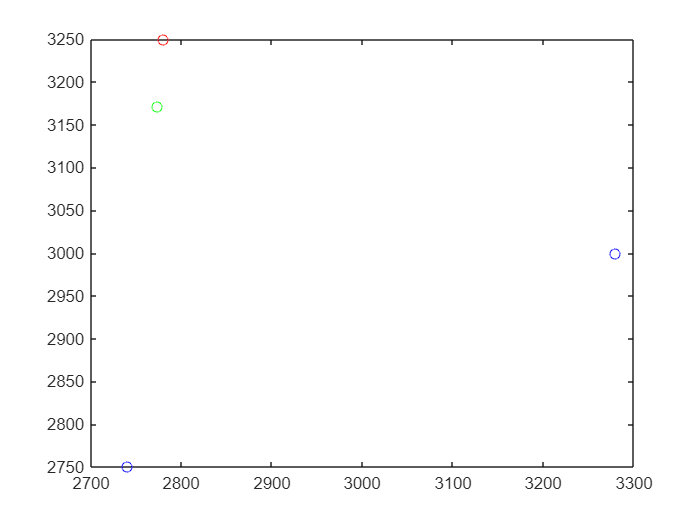


close
figure
plot(Model2.Surnode(:,1),Model2.Surnode(:,2),'bo');
hold on
plot(Model2.Airnode(:,1),Model2.Airnode(:,2),'ko');
plot(Temp_T2(1),Temp_T2(2),'go');
plot(Temp_L2(1),Temp_L2(2),'ro');

Model3.Airnode = [3280 3000
                  3250 2500];
Model3.centrol = [3260	2750];
Model3.Surnode = [3280	3000
                    3240	2500
                    3200	2000];
Model3.CostAir = [800; 800];
Model3.CostSur = [800; 800; 800];
ub = [Model3.Airnode(1,1)+range,Model3.Airnode(1,2)+range];
lb = [Model3.Airnode(1,1)-range,Model3.Airnode(1,2)-range];

[Temp_T3, GBestFitness, Temp_L3] = PSOsolveTemp(Model3, Vel, ub, lb, iter_Max, N)

Temp_T3 = 1.0e+03 *

    3.2800    3.0000


GBestFitness = 1.0e+03 *

    1.4144    1.4063    1.4054    1.4046    1.4043    1.4042    1.4042    1.4040    1.4040    1.4040    1.4040    1.4040    1.4040    1.4040    1.4040    1.4040    1.4040    1.4039    1.4039    1.4039    1.4039


Temp_L3 = 1.0e+03 *

    2.9415    2.5000


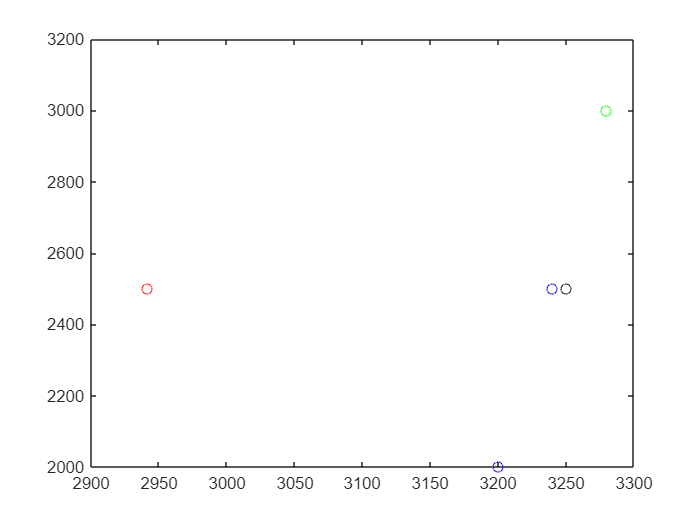


close
figure
plot(Model3.Surnode(:,1),Model3.Surnode(:,2),'bo');
hold on
plot(Model3.Airnode(:,1),Model3.Airnode(:,2),'ko');
plot(Temp_T3(1),Temp_T3(2),'go');
plot(Temp_L3(1),Temp_L3(2),'ro');

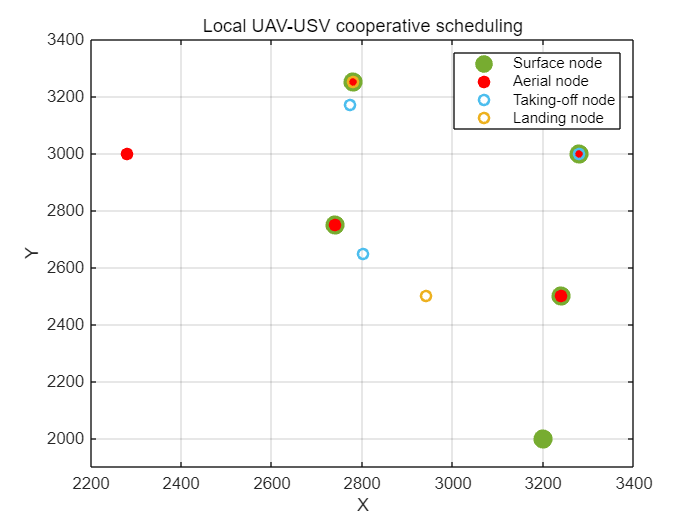

close
Model3.Airnode = [3280 3000
                  3240 2500];
Surnode =  [Model1.Surnode
            Model2.Surnode
             Model3.Surnode];

Airnode = [Model1.Airnode
            Model2.Airnode
            Model3.Airnode];

Temp_T = [Temp_T1
    Temp_T2
    Temp_T3];

Temp_L = [Temp_L1
    Temp_L2
    Temp_L3];

figure
plot([Surnode(:, 1)], [Surnode(:, 2)], 'o', 'Color', "#77AC30" ,'MarkerFaceColor', "#77AC30",'MarkerSize',10,'LineWidth',1.5);
hold on;
plot([Airnode(:, 1)], [Airnode(:, 2)], 'o', 'Color', "#FF0000" ,'MarkerFaceColor', '#FF0000','MarkerSize',6,'LineWidth',1.5);
plot([Temp_T(:, 1)], [Temp_T(:, 2)], 'o', 'Color', "#4DBEEE" ,'MarkerSize',6,'LineWidth',1.5);
plot([Temp_L(:, 1)], [Temp_L(:, 2)], 'o', 'Color', "#EDB120" ,'MarkerSize',6,'LineWidth',1.5);


hold off
legend('Surface node','Aerial node','Taking-off node','Landing node')
axis([2200 3400 1900 3400])
title('Local UAV-USV cooperative scheduling');
xlabel('X');
ylabel('Y');
grid on;